**P.58**

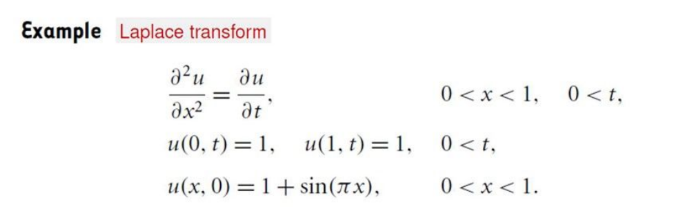

clc;clearvars;
syms x t s u(x,t) U(x,s) Y(x)
Dt = diff(u,t);
D2x = diff(u,x,2);
eqn = laplace(Dt == D2x,t,s);
cond0 = u(0,t) == 1;
cond1 = u(1,t) == 1;
init = 1+sin(pi*x);
eqn = subs(eqn,{laplace(u,t,s),u(x,0),laplace(D2x,t,s)},{U(x,s),init,subs(D2x,{u,t},{U,s})})

$$eqn(x) = s\,U\left(x,s\right)-\sin\left(\pi \,x\right)-1=\frac{\partial^{2}}{\partial x^{2}}U\left(x,s\right)$$

cond0_s = laplace(cond0,t,s);
cond1_s = laplace(cond1,t,s);
cond0_s = subs(cond0_s,laplace(u(0,t),t,s),U(0,s))

$$cond0\_s = U\left(0,s\right)=\frac{1}{s}$$

cond1_s = subs(cond1_s,laplace(u(1,t),t,s),U(1,s))

$$cond1\_s = U\left(1,s\right)=\frac{1}{s}$$

eqn_n = subs(eqn,U,Y)

$$eqn\_n(x) = s\,Y\left(x\right)-\sin\left(\pi \,x\right)-1=\frac{\partial^{2}}{\partial x^{2}}Y\left(x\right)$$

cond0_s = subs(cond0_s,U,Y)

$$cond0\_s = Y\left(0\right)=\frac{1}{s}$$

cond1_s = subs(cond1_s,U,Y)

$$cond1\_s = Y\left(1\right)=\frac{1}{s}$$

sol = dsolve(eqn_n,[cond0_s cond1_s])

$$sol = \frac{s+s\,\sin\left(\pi \,x\right)+\pi^{2}}{s\,\left(s+\pi^{2}\right)}$$

sol_t = ilaplace(sol,s,t)

$$sol\_t = {\mathrm{e}}^{-t\,\pi^{2}}\,\sin\left(\pi \,x\right)+1$$

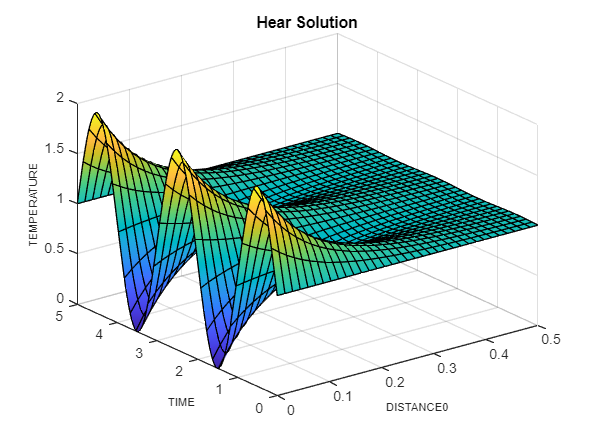

fsurf(sol_t,[0 0.5 0 5])
title("Hear Solution")
xlabel('DISTANCE0','FontSize',8);
ylabel('TIME','FontSize',8)
zlabel('TEMPERATURE','FontSize',8)